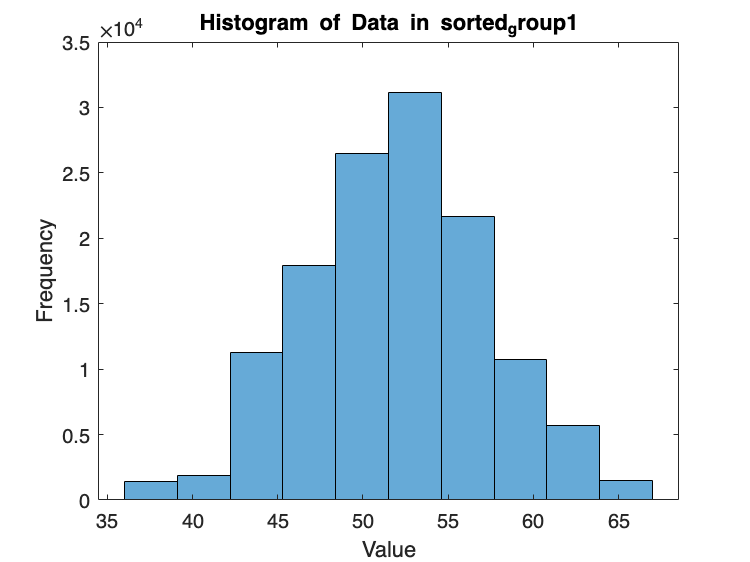

clc;clear; 
% Define the file paths for your CSV files
file1 = '/Users/ibraga/Desktop/Glucose_x_fructose/Mouse 1/1_Baseline-Glu-1.csv';
file2 = '/Users/ibraga/Desktop/Glucose_x_fructose/Mouse 1/2_Glu-1.csv';
file3='/Users/ibraga/Desktop/Glucose_x_fructose/Mouse 1/3_Baseline-Fluc-1.csv';
file4= '/Users/ibraga/Desktop/Glucose_x_fructose/Mouse 1/4_Fluc-1.csv';


% Read the CSV data from the files into tables
table1 = readtable(file1);
table2 = readtable(file2);
table3 = readtable(file3);
table4 = readtable(file4);
% Extract the data without the first column (assuming non-numeric data is in the first column)
data1 = table2array(table1(:, 2:end));
data2 = table2array(table2(:, 2:end));
data3 = table2array(table3(:, 2:end));
data4 = table2array(table4(:, 2:end));

% Check if the number of columns in all datasets is the same
if size(data1, 2) ~= size(data2, 2) || size(data1, 2) ~= size(data3, 2) || size(data1, 2) ~= size(data4, 2)
    error('The number of columns in the CSV files must be the same.');
end

% Merge the data from all datasets while appending rows
data1 = [data1; data2];
data2= [data3; data4];
% For sorted_group1
figure;
histogram(data1(:), 10); % Adjust the number of bins as needed
title('Histogram of Data in sorted_group1');
xlabel('Value');
ylabel('Frequency');

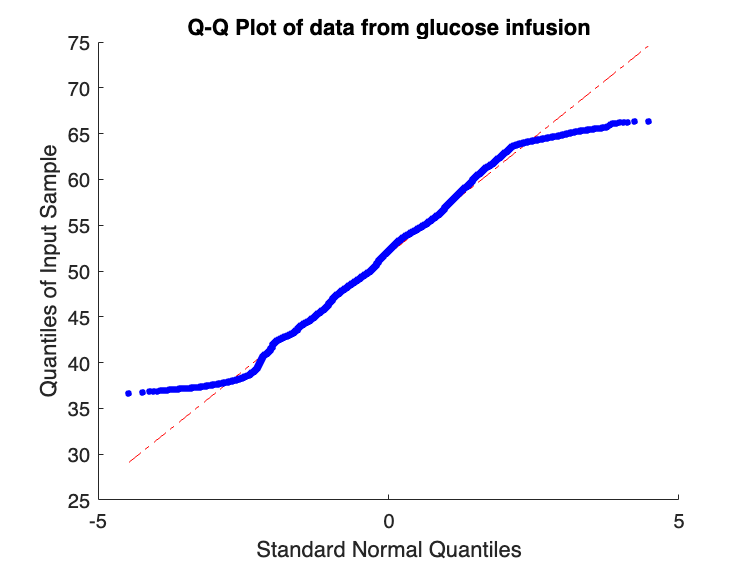


% For sorted_group1
figure;
% Modify the Q-Q plot to use dots as data points
h = qqplot(data1(:));
title('Q-Q Plot of data from glucose infusion');
% Modify the Q-Q plot to use dots as data points
set(h(1), 'Marker', '.');  % Sets the marker style for data points
set(h(1), 'MarkerSize', 10);  % Adjust the marker size

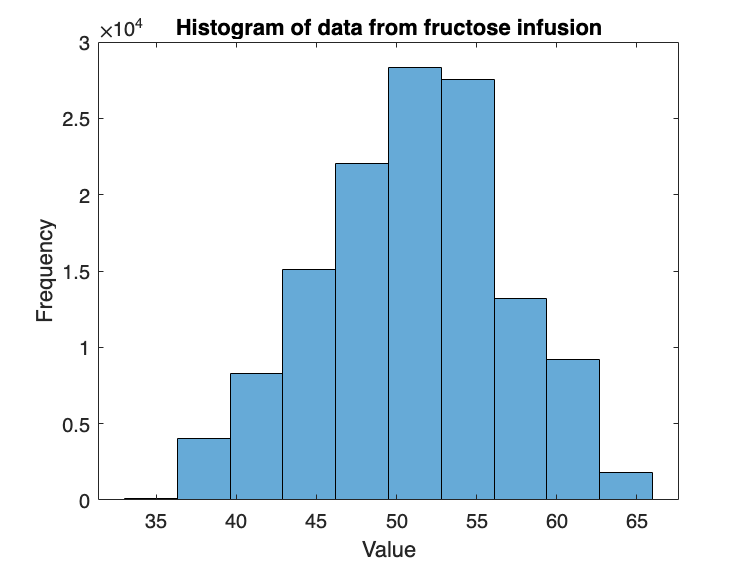


% For sorted_group1
figure;
histogram(data2(:), 10); % Adjust the number of bins as needed
title('Histogram of data from fructose infusion');
xlabel('Value');
ylabel('Frequency');

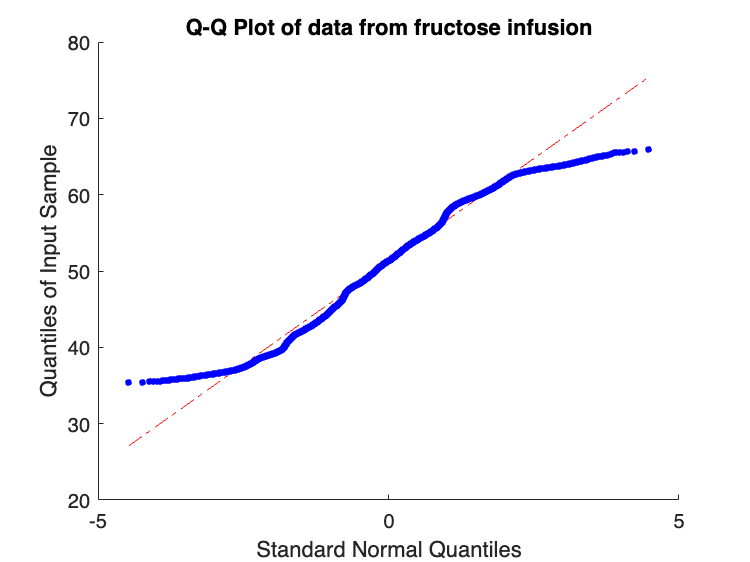

h = qqplot(data2(:));
title('Q-Q Plot of data from fructose infusion');

% Modify the Q-Q plot to use dots as data points
set(h(1), 'Marker', '.');  % Sets the marker style for data points
set(h(1), 'MarkerSize', 10);  % Adjust the marker size

Finding the intensities for 360 min

% Define the interval for averaging (every tenth value)
interval = 10;

% Calculate the number of rows after averaging
numRowsAfterAveraging = floor(size(data1, 1) / interval);

% Initialize the "average" variable with the correct dimensions
average1 = zeros(numRowsAfterAveraging, size(data1, 2));

% Loop through each column
for col = 1:size(data1, 2)
    % Extract the data from the current column
    currentData = data1(:, col);
    
    % Calculate the average of every tenth value
    for i = 1:numRowsAfterAveraging
        startIndex = (i - 1) * interval + 1;
        endIndex = i * interval;
        segment = currentData(startIndex:endIndex);
        average1(i, col) = mean(segment);
    end
end

Calclating baseline mean, std and data z-scores (all negative z-scores were set to 0)

% Prompt the user to enter the baseline duration in seconds
baselineDuration = input('Enter the duration of the baseline in seconds: ');

% Calculate the mean and standard deviation for each column from the first row to the rows equivalent to the baseline
meanValues = mean(average1(1:baselineDuration, :), 1);
stdDevValues = std(average1(1:baselineDuration, :), 1);
baselineStats = [meanValues; stdDevValues];

% Initialize a variable to store z-scores
zScores1 = zeros(size(average1));

% Loop through each neuron (column)
for col = 1:size(average1, 2)
    % Extract the mean and standard deviation for the current neuron from baselineStats
    meanValue = baselineStats(1, col);
    stdDevValue = baselineStats(2, col);
    
    % Calculate z-scores for each point in the current neuron's column
    zScores1(:, col) = (average1(:, col) - meanValue) / stdDevValue;
    
    % Set negative z-scores to zero
    zScores1(zScores1(:, col) < 0, col) = 0;
end

Plotting, please input the graph title when prompted 

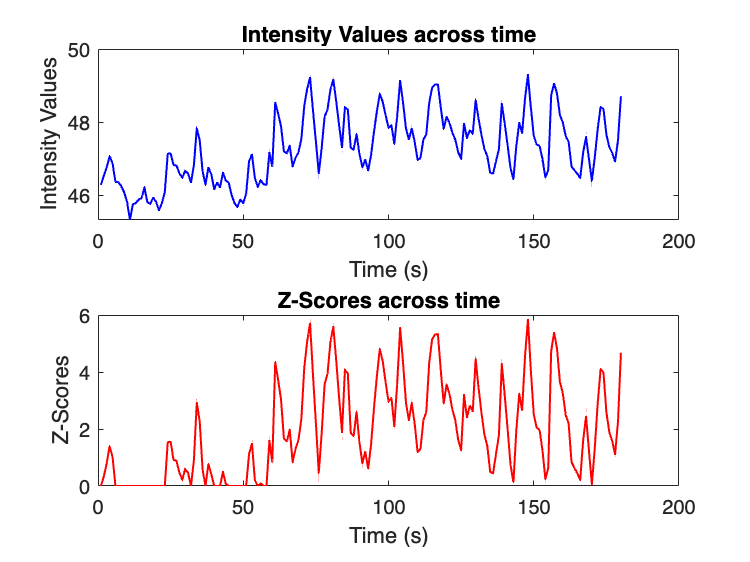

% Assuming you have 'average1' and 'zscores1' matrices

% Generate a random column index
num_neurons = size(average1, 2);
random_column_index = randi(num_neurons);

% Select the random column from 'average1' and 'zscores1'
random_column_average = average1(:, random_column_index);
random_column_zscores = zScores1(:, random_column_index);

% Create a time vector (assuming you have the time information)
time_in_hr = 1:size(average1, 1);  % Adjust this if your time information is different

% Plot the data for 'average1' as a line graph
figure;
subplot(2, 1, 1);  % Create the first subplot
plot(time_in_hr, random_column_average, 'b', 'LineWidth', 1);
title('Intensity Values across time');
xlabel('Time (s)');
ylabel('Intensity Values');

% Plot the data for 'zscores1' as a line graph
subplot(2, 1, 2);  % Create the second subplot
plot(time_in_hr, random_column_zscores, 'r', 'LineWidth', 1);
title('Z-Scores across time');
xlabel('Time (s)');
ylabel('Z-Scores');

% 
% %Sort the rows of zScores based on the maximum z-score for each neuron
% % [~, sortIdx] = sort(max(zScores, [], 1), 'descend');
% % sortedZScores = zScores(:, sortIdx);
% % Calculate the mean z-score for each neuron
% meanZScores = mean(zScores, 1);
% 
% % % Sort the neurons based on their mean z-scores from highest to lowest
% [~, sortIdx] = sort(meanZScores, 'descend');
% 
% % % Rearrange the columns (neurons) of zScores based on the sorting order
% sortedZScores = zScores(:, sortIdx);
% % % Set the z-score threshold
%  zScoreThreshold = 2.5;
% 
% % Initialize an index array to keep track of neurons to keep
% neuronsToKeep = true(1, size(sortedZScores, 2));
% 
% % Loop through the neurons and check their z-scores
% for i = 1:size(sortedZScores, 2)
%     neuronZScores = sortedZScores(:, i);
%     % Check if all z-scores for the current neuron are less than the threshold
%     if all(neuronZScores <= zScoreThreshold)
%         neuronsToKeep(i) = false;
%     end
% end
% 
% % Use logical indexing to keep only the neurons that meet the criteria
% filteredZScores = sortedZScores(:, neuronsToKeep);
% 
% 
% % Prompt the user for a custom title
% customTitle = input('Enter a custom title for the heatmap: ', 's');
% % Prompt the user to enter the name of the stimulus
% stimulusName = input('Enter the type of the stimulus: ', 's');
% % Create a heatmap with sorted rows
% figure;
% imagesc(filteredZScores');  % Transpose sortedZScores to have neurons on the y-axis
% colorbar;  % Display a colorbar
% 
% % Set the axis limits to match the size of the heatmap
% axis([0.5, size(filteredZScores, 1) + 0.5, 0.5, size(filteredZScores, 2) + 0.5]);
% 
% % Add labels and titles
% hTitle =title(customTitle);
% ylabel('Neurons');
% xlabel('Time (s)');
% set(gca, 'FontSize', 14);
% % Adjust the font size for title, x-axis label, and y-axis label
% set(hTitle, 'FontSize', 16);
% 
% % Adjust the color scale to highlight differences
% caxis([0, max(filteredZScores(:))]);  % Set the color scale from 0 to the maximum z-score
% % Display the name of the stimulus vertically along the white line
% % Adjust the color scale to limit it to a maximum value of 20
% caxis([0, 13]);
% 
% % Optionally, you can set a colormap for the heatmap
% colormap('jet');  % You can choose a different colormap if desired
% 
% % Show the heatmap
% 
% % Optionally, you can set a colormap for the heatmap
% colormap('jet');  % You can choose a different colormap if desired
% 
% % Show the heatmap
% %Add a vertical dashed white line at the x-coordinate equivalent to the baseline
% baselineLineX = baselineDuration; % Calculate the x-coordinate
% baselineLineY = [0.5, size(filteredZScores, 2) + 0.5]; % Set the y-coordinates
% line([baselineLineX, baselineLineX], baselineLineY, 'Color', 'white', 'LineStyle', '--');
% % Display the name of the stimulus alongside the white line at the top
% text(baselineLineX, min(baselineLineY)+10, stimulusName, 'Color', 'white', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'Rotation', 90, 'FontSize', 14);

% 
% 
% % Save the data to a file with a filename based on stimulusName
% filename = ['filteredZScores_', customTitle, '.mat'];
% save(filename, 'filteredZScores');
% % Save the heatmap image as a PNG file (you can change the format as needed)
% heatmapFilename = ['heatmap_', stimulusName, '.png'];
% saveas(gcf, heatmapFilename);
% 
% disp(['Heatmap image saved as ' heatmapFilename]);
